正在生成场景 A (100x100, T=50)...
开始向量化仿真: 10000 像素, BatchSize = 262...
仿真完成! 耗时: 44.0943 秒


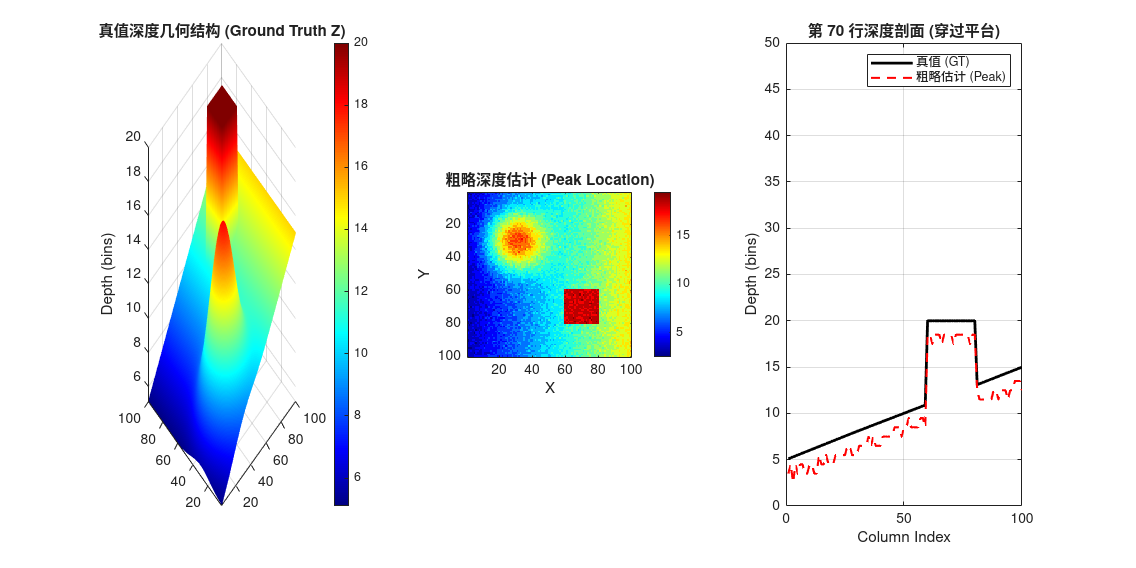


场景特征说明:
1. 左上角: 光滑高斯隆起。
2. 背景: 沿X轴的线性坡面。
3. 右下角 (60:80): 突变的矩形平台。
4. 反射率: 全局均匀 (0.8)。


%% 向量化 SPAD 2D 场景仿真验证
clear; clc; close all;

run('simMAP_A.mlx')

% =========================================================================
% 4. 执行反演 (Reconstruction)
% =========================================================================
% 配置参数
opts = struct();
opts.rho = 1.0;
opts.gamma_z = 2.0;  % 深度平滑权重 (二阶)
opts.gamma_a = 0.5;  % 反射率平滑权重
opts.max_iter = 20;
opts.mu_ratio = 50;  % 线性化参数

[Z_est, A_est, history] = LidarReconADMM.reconstruct(hist_cube, pulse_params, N_shots, ...
    'rho', opts.rho, 'gamma_z', opts.gamma_z, 'gamma_a', opts.gamma_a, ...
    'max_iter', opts.max_iter, 'mu_ratio', opts.mu_ratio);

开始 ADMM 重建 (M=100, N=100, T=50)...
Iter  1 | Diff: 1.05e-01 | Time: 0.47s
Iter  5 | Diff: 7.98e-04 | Time: 2.21s
Iter 10 | Diff: 1.71e-04 | Time: 4.44s
Converged at iter 14.


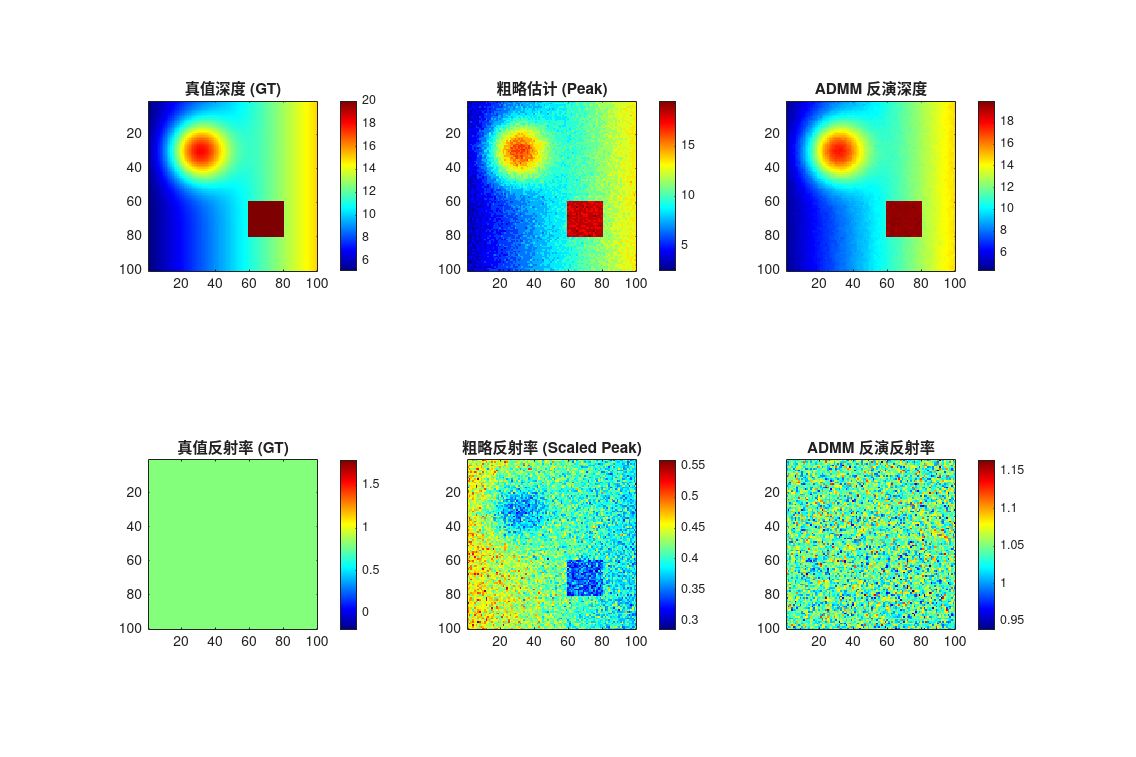


% =========================================================================
% 5. 结果可视化
% =========================================================================
% 简单的峰值检测作为对比 (Baseline)
[~, max_idx] = max(hist_cube, [], 3);
Z_coarse = double(max_idx) - pulse_params.mu;

figure('Name', 'Reconstruction Results', 'Color', 'w', 'Position', [100, 100, 1200, 800]);

% --- 深度对比 ---
subplot(2, 3, 1); imagesc(Z_gt); axis image; colorbar; title('真值深度 (GT)');
subplot(2, 3, 2); imagesc(Z_coarse); axis image; colorbar; title('粗略估计 (Peak)');
subplot(2, 3, 3); imagesc(Z_est); axis image; colorbar; title('ADMM 反演深度');

% --- 反射率对比 ---
subplot(2, 3, 4); imagesc(A_gt); axis image; colorbar; title('真值反射率 (GT)');
subplot(2, 3, 5); 
% 粗略反射率估计 (Peak Value / N)
peak_vals = max(hist_cube, [], 3);
imagesc(peak_vals / N_shots * 5); axis image; colorbar; title('粗略反射率 (Scaled Peak)');
subplot(2, 3, 6); imagesc(A_est); axis image; colorbar; title('ADMM 反演反射率');

colormap jet;

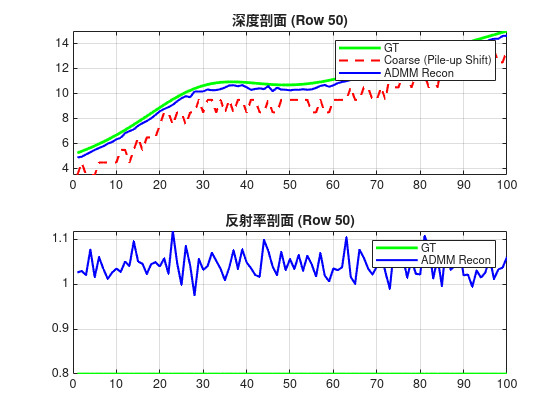


% --- 剖面线对比 (选取中间一行) ---
mid_row = round(M/2);
figure('Name', 'Profile Comparison', 'Color', 'w');
subplot(2,1,1);
plot(Z_gt(mid_row, :), 'g-', 'LineWidth', 2); hold on;
plot(Z_coarse(mid_row, :), 'r--', 'LineWidth', 1.5);
plot(Z_est(mid_row, :), 'b-', 'LineWidth', 1.5);
legend('GT', 'Coarse (Pile-up Shift)', 'ADMM Recon');
title(['深度剖面 (Row ' num2str(mid_row) ')']); grid on;

subplot(2,1,2);
plot(A_gt(mid_row, :), 'g-', 'LineWidth', 2); hold on;
plot(A_est(mid_row, :), 'b-', 'LineWidth', 1.5);
legend('GT', 'ADMM Recon');
title(['反射率剖面 (Row ' num2str(mid_row) ')']); grid on;


% --- 误差统计 ---
z_rmse = sqrt(mean((Z_est(:) - Z_gt(:)).^2));
a_rmse = sqrt(mean((A_est(:) - A_gt(:)).^2));
fprintf('\n重建精度:\n');


重建精度:


fprintf('Depth RMSE: %.4f bins\n', z_rmse);

Depth RMSE: 0.3790 bins


fprintf('Reflectivity RMSE: %.4f\n', a_rmse);

Reflectivity RMSE: 0.2444




% --- 验证说明 ---
fprintf('\n验证分析:\n');


验证分析:


fprintf('1. 高反区域 (红色曲线) 应该表现出明显的 Pile-up 特征：\n');

1. 高反区域 (红色曲线) 应该表现出明显的 Pile-up 特征：


fprintf('   - 峰值左移 (相对于真值虚线)\n');

   - 峰值左移 (相对于真值虚线)


fprintf('   - 尾部截断 (指数衰减极快)\n');

   - 尾部截断 (指数衰减极快)


fprintf('2. 普通区域 (蓝色曲线) 应该接近对称的高斯/逆高斯形状。\n');

2. 普通区域 (蓝色曲线) 应该接近对称的高斯/逆高斯形状。
